# **GFL・GFMの組み合わせ最適選択をしてみよう !!**

## 先ほどと同じようにGUILDAに実装済みの標準モデルを呼び出してみましょう !!

% net_origin = network.IEEE14bus; 
clear net_origin
net_origin = IEEE14bus; 

INFO: Slack bus not found. Setting the first bus 'B001' as the slack bus.
INFO: B001 set as slack bus. 
      P and Q specifications for SG1B001 ignored in powerflow calculation.


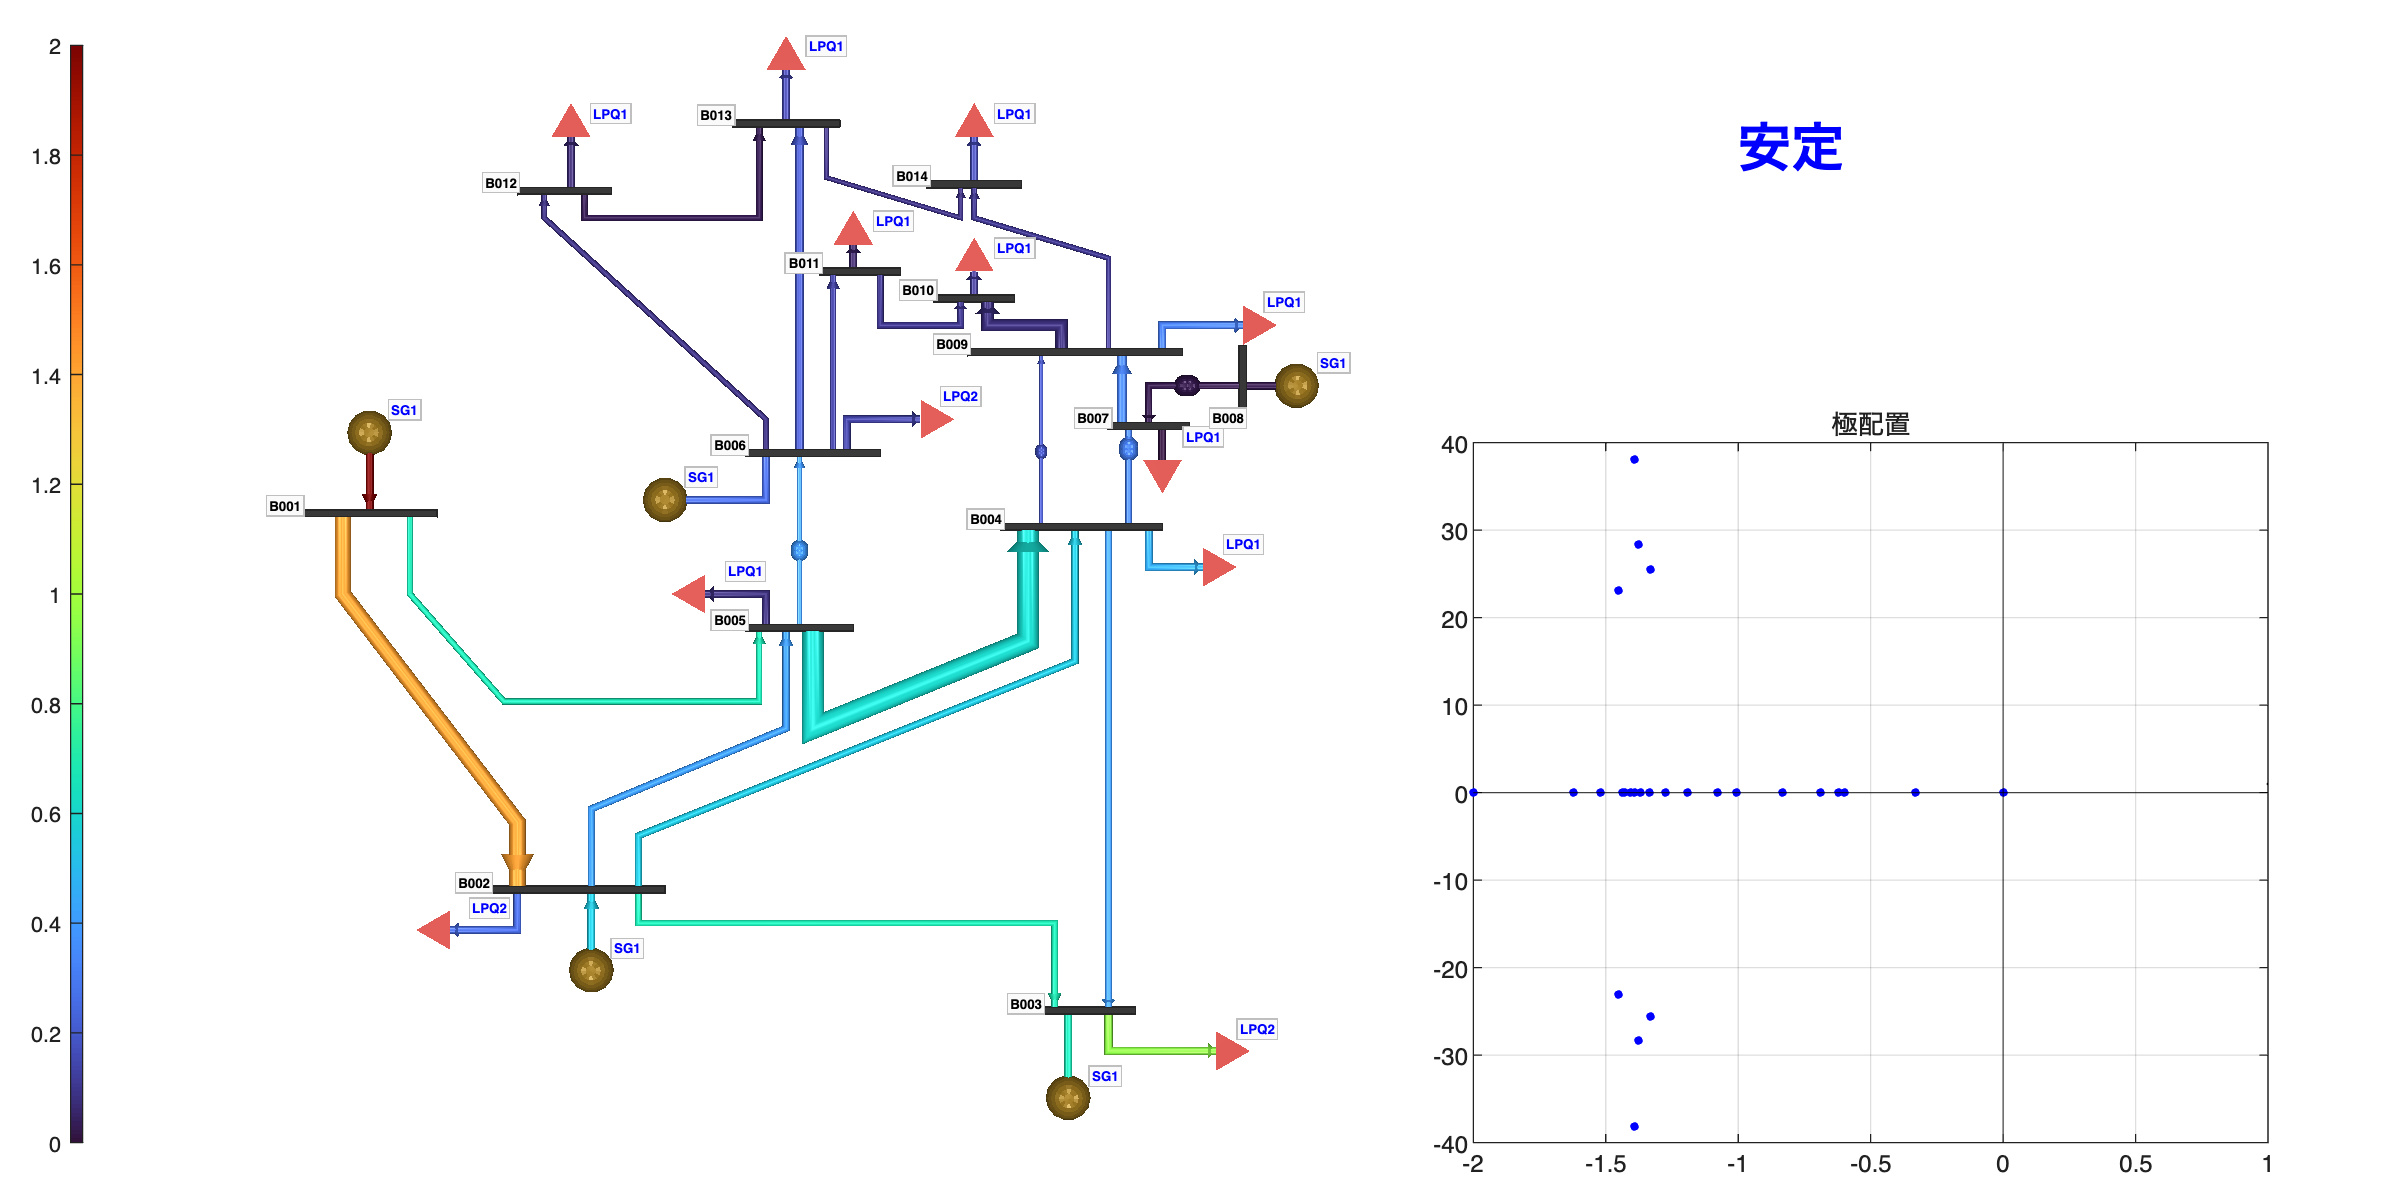

 
INV_past = repmat(2,[1,4]);
base_bus = net_origin.a_Bus([3,9,12,14]);
base_comp_name = ["LPQ2B003","LPQ1B009","LPQ1B012","LPQ1B014"];

a_Component_origin = tools.vcellfun(@(b) b.a_Component, net_origin.a_Bus);
get_PQ   = @(p) [p.P, p.Q];
rv_defPQ = tools.vcellfun(@(c) get_PQ(c.para_powerflow), a_Component_origin);
[Graph_origin, txt_origin, sct_origin] = func.new_plot(net_origin);

% func.update_plot(net, Graph, txt, sct);

## なんか凄そうなグラフが出てきましたね。

#### 左のグラフは系統図を表しています。

#### 系統内に流れている潮流の大きさや各送電線における電力の流れやすさが可視化されていて分かりやすいですね。

#### 次に、右のグラフを見てみましょう。これは、IEEE14母線系統を平衡点周りで近似線形化したシステムのA行列の固有値を見ています。

#### 制御を勉強している人なら分かると思いますが、線形システムが安定であることと、A行列の固有値が複素平面上の左半平面に存在することは

#### 等価でしたね。上記のグラフを見てみると、ゼロ固有値を除いたすべての固有値が左半平面上に存在することから安定であることが分かります。

## では次に、負荷の比率を増減させてみましょう

#### 下にalphaという変数があります。これは、系統に接続されているすべての負荷をalpha倍するためのものです。

#### 適当な値を選んで、実行を押してみましょう。


alpha_origin =1.72 

alpha_origin = 1.7200

mulitiple_alpha(a_Component_origin, rv_defPQ, alpha_origin)
fprintf(" >> 潮流計算中          ...")

 >> 潮流計算中          ...

net_origin.initialize;
disp(" ok!!")

 ok!!


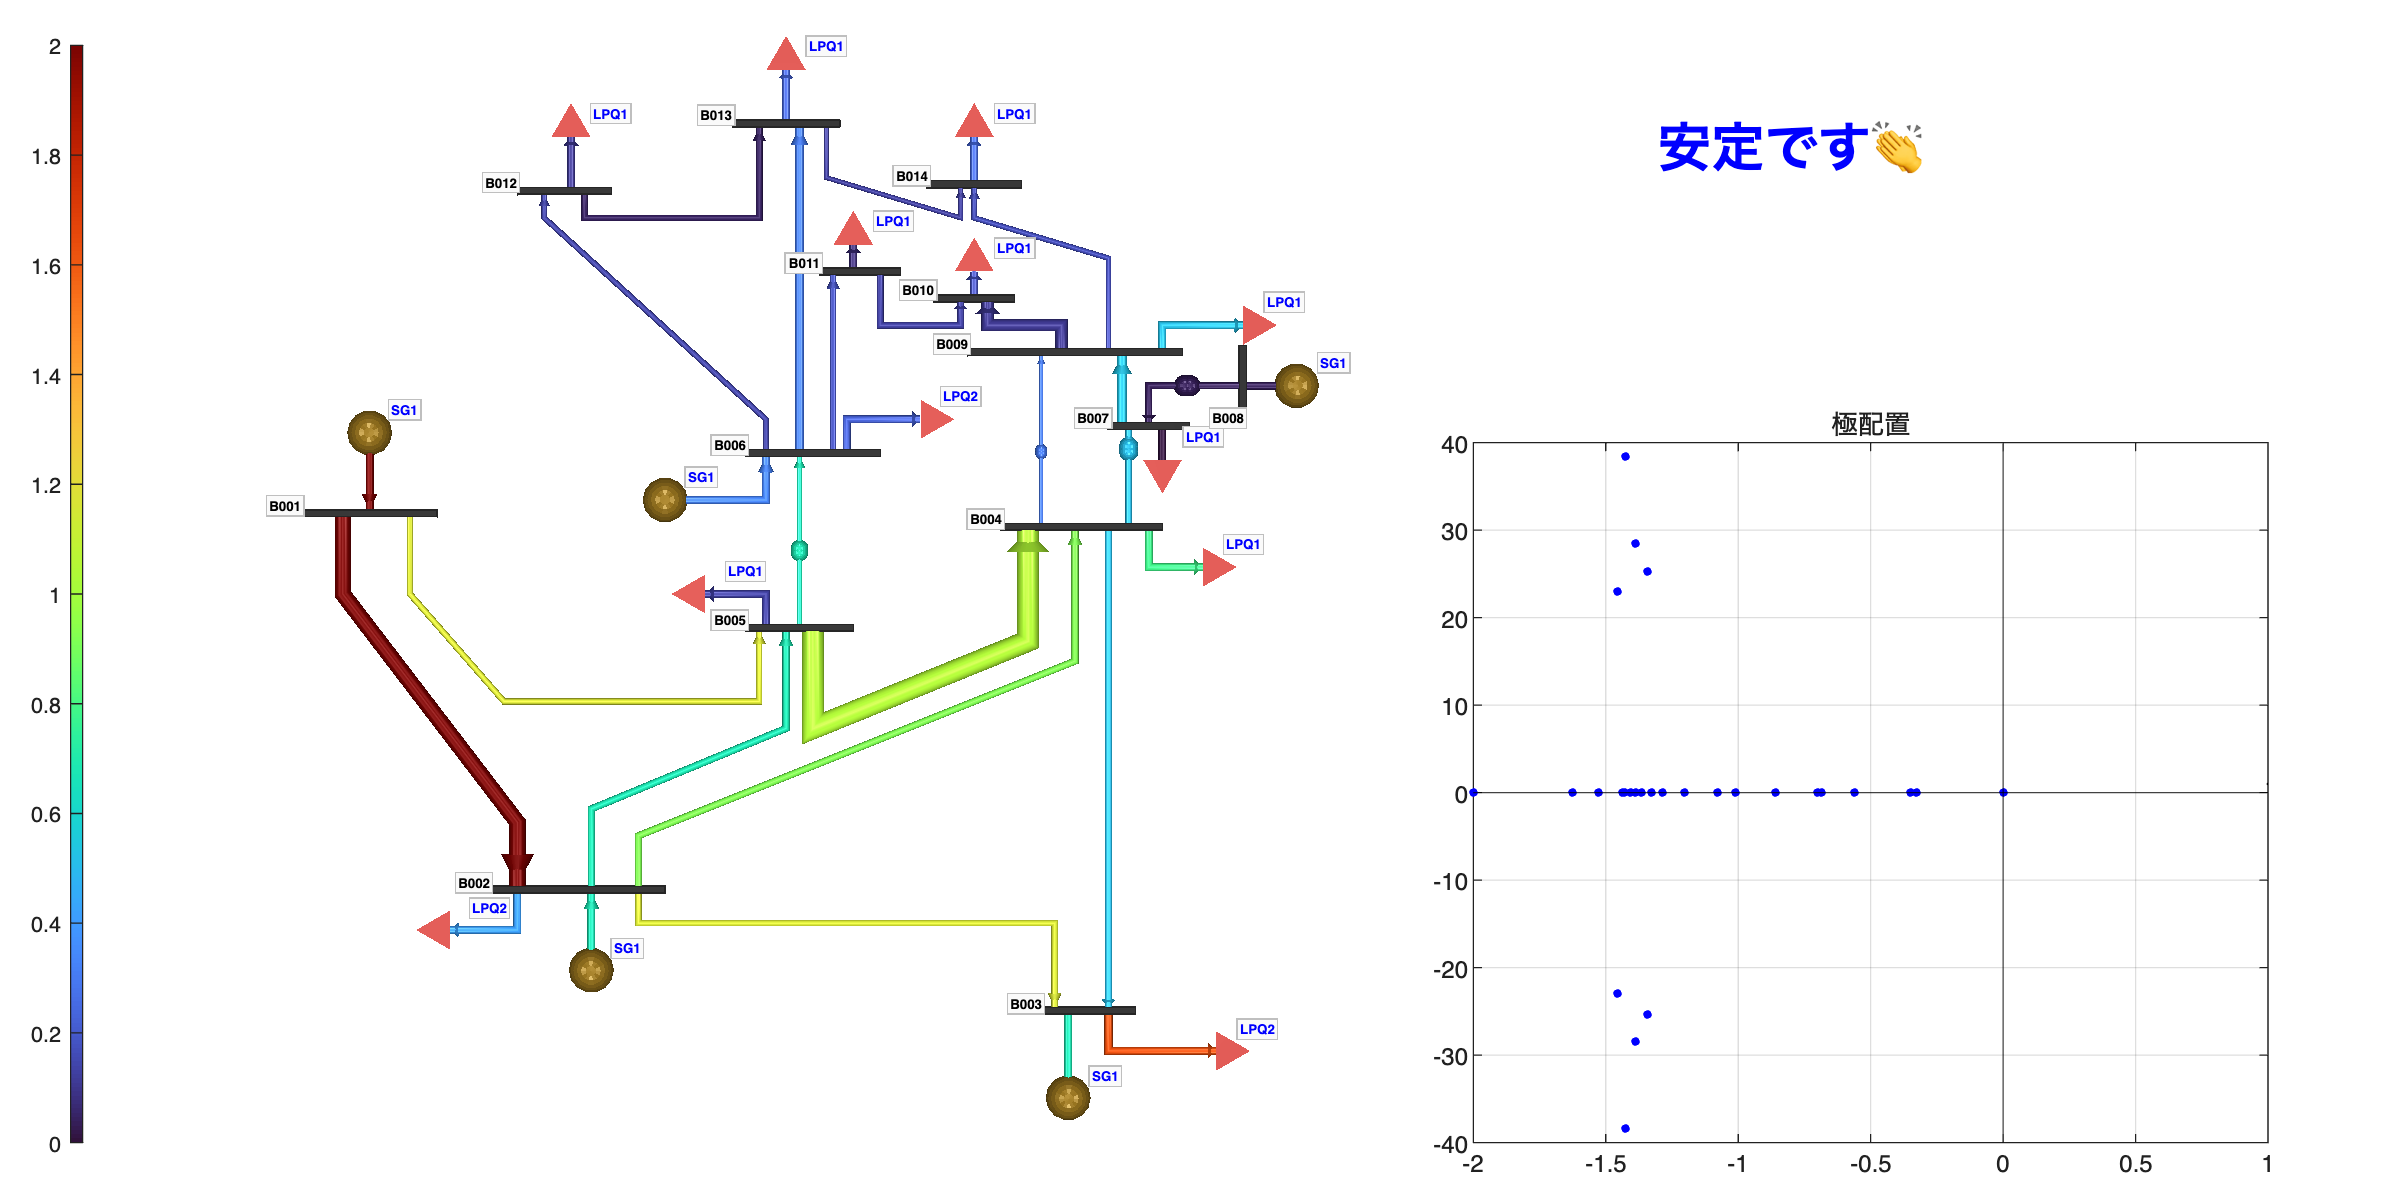

 >> グラフプロットに反映中... ok!!
 >> 極配置プロットに反映中... ok!!


[Graph_origin_2, txt_origin_2, sct_origin_2] = func.new_plot(net_origin);
func.update_plot(net_origin, Graph_origin_2, txt_origin_2, sct_origin_2);

% [Graph, txt, sct] = func.new_plot(net);

## 結果が出ましたね

#### 指定した負荷の比率によっては系統が不安定化した人もいると思います。

#### このように、同じシステムを対象にしていたとしても、潮流設定によって安定度が変化することが分かります。

# **系統の構成を変更して最大の倍率を求めてみよう !!**

#### **図のように母線3,9,12,14ではGFM,GFLの選択ができるようになっています。**

#### **自由に機器を選択して、系統の挙動がどのように変わるのか確認してみましょう。**

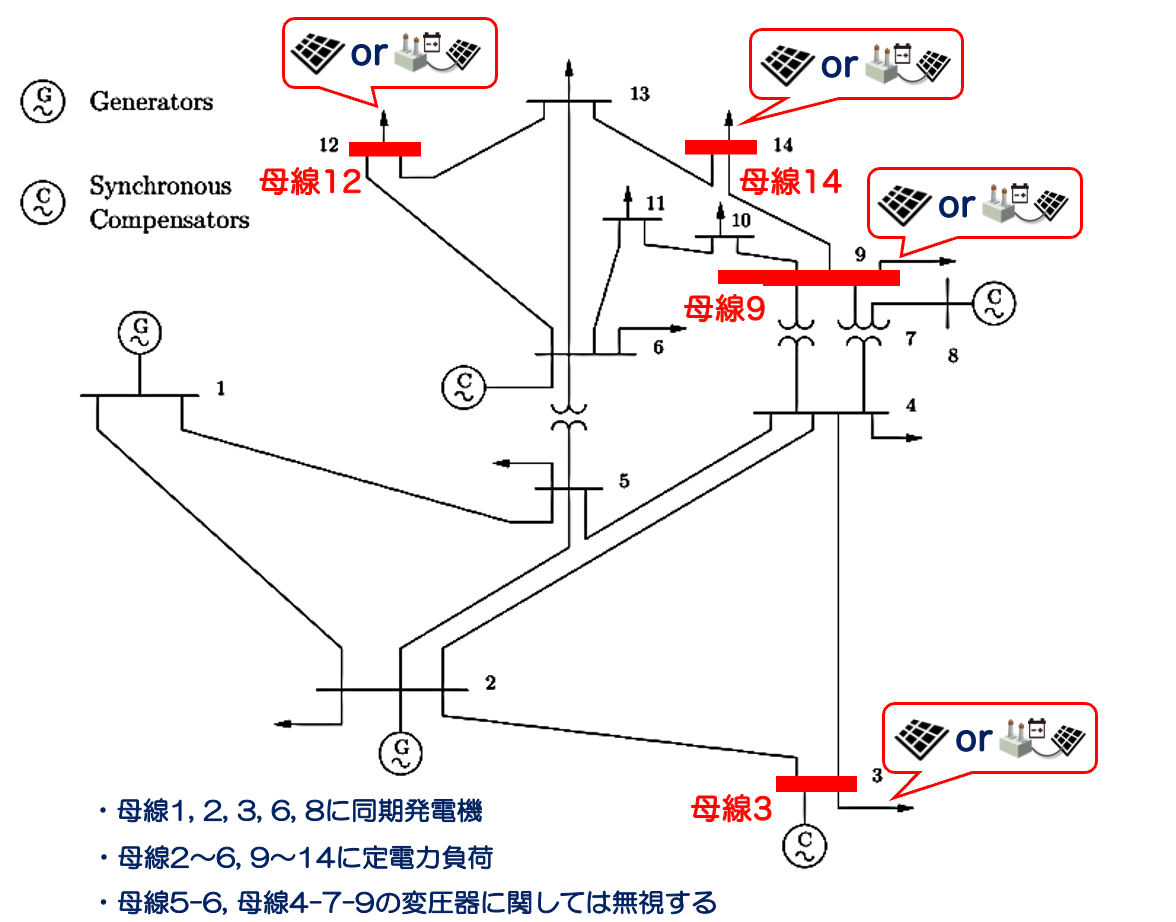

INV1 = 1;
INV2 = 2;
INV3 = 1;
INV4 = 2;

alpha2 =2.81;
 

net_alpha = IEEE14bus(false);

baseBus = net_alpha.a_Bus([3,9,12,14]);
baseComponentName = ["LPQ2B003","LPQ1B009","LPQ1B012","LPQ1B014"];

listInverter = [INV1;INV2;INV3;INV4];

tab_VSG = array2table(repmat([10,2,0.40,0.20],[4,1]), 'VariableNames', {'M','D','Xd','Xq'});

replace_component(listInverter, baseComponentName, tab_VSG, baseBus)

a_Component_alpha = tools.vcellfun(@(b) b.a_Component, net_alpha.a_Bus);
rv_defPQ_alpha = tools.vcellfun(@(c) get_PQ(c.para_powerflow), a_Component_alpha);
mulitiple_alpha(a_Component_alpha, rv_defPQ_alpha, alpha2);

net_alpha.initialize;

INFO: Slack bus not found. Setting the first bus 'B001' as the slack bus.
INFO: B001 set as slack bus. 
      P and Q specifications for SG1B001 ignored in powerflow calculation.


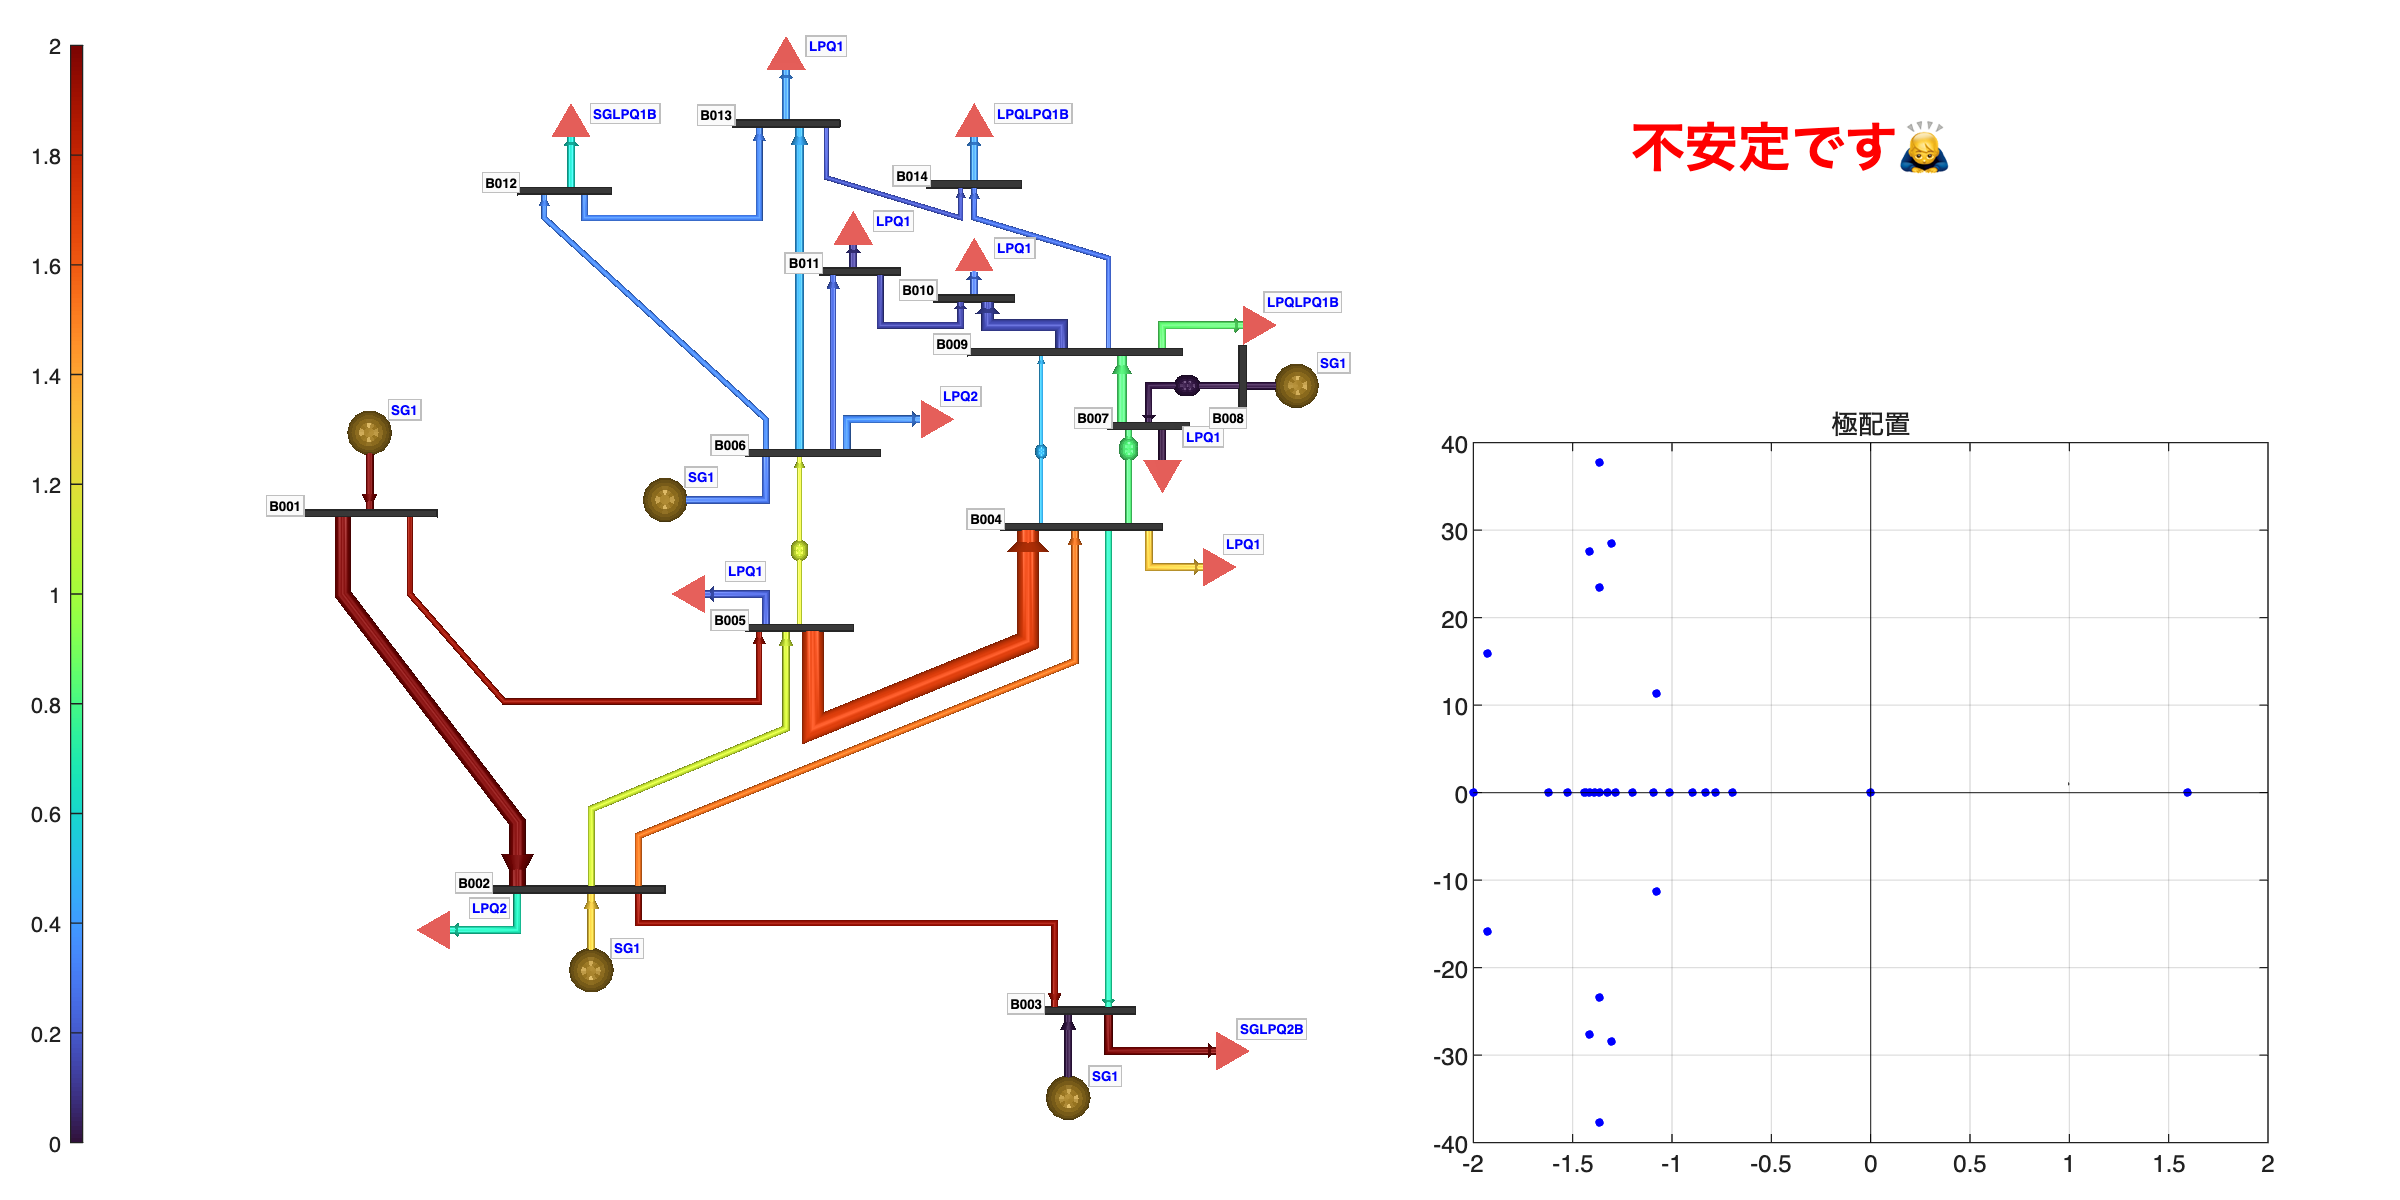

 >> グラフプロットに反映中... ok!!
 >> 極配置プロットに反映中... ok!!



[Graph2, txt2, sct2] = func.new_plot(net_alpha);
func.update_plot(net_alpha, Graph2, txt2, sct2);

#### GFL・GFMを切り替えることによって系統がその程度の負荷変動を許容量が変化したと思います。

# **GFL・GFMの組み合わせ最適選択をしてみよう !!**

#### **先ほどの説明では以下の式の正負が系統の安定性に深く関わっていました。**

 

#### **今度は上記の式が非負ならGFM、負ならGFLを選ぶことによって系統の安定度を最大化してみましょう。**

### **まずは、GFMのパラメータを設定します。設定が完了したら、計算を押してみましょう。**

**母線3に接続するGFMのパラメータ**

Xd3 = 5;
Xq3 = 4;

**母線9に接続するGFMのパラメータ**

Xd9 = 1;
Xq9 = 1;

**母線12に接続するGFMのパラメータ**

Xd12 = 0.64;
Xq12 = 0.32;

**母線14に接続するGFMのパラメータ**

Xd14 = 1.2;
Xq14 = 0.8;

 

net_final = IEEE14bus();

INFO: Slack bus not found. Setting the first bus 'B001' as the slack bus.
INFO: B001 set as slack bus. 
      P and Q specifications for SG1B001 ignored in powerflow calculation.


base_bus_final = net_final.a_Bus([3,9,12,14]);
Is = zeros(4,1);
for IS = 1:4
    Is(IS) = base_bus_final{IS}.a_Component{end}.c_Iequilibrium;
end
Vs = cellfun(@(BS) BS.c_Vequilibrium, base_bus_final);
Ps = arrayfun(@(VS, IS) real(VS*conj(IS)), Vs, Is);
Qs = arrayfun(@(VS, IS) imag(VS*conj(IS)), Vs, Is);

Vabs = arrayfun(@(VS) abs(VS), Vs);

XQ = [Xq3;Xq9;Xq12;Xq14];
XD = [Xd3;Xd9;Xd12;Xd14];

GFMterm = arrayfun(@(PS, QS, VS, XQs, XDs) calc_GFMterm(PS, QS, VS, XQs, XDs), Ps, Qs, Vabs, XQ, XD);

iv_GFMT = [3,9,12,14];
for GFMT = 1:4
    disp("母線"+iv_GFMT(GFMT)+"における(*)の計算結果: "+string(GFMterm(GFMT)))
end

母線3における(*)の計算結果: -1.0157
母線9における(*)の計算結果: 54.4712
母線12における(*)の計算結果: 22525.024
母線14における(*)の計算結果: 294.502


### 計算結果が出ましたね。ではその結果に基づいて、GFM・GFLの選択をしてみましょう。

TAB = table(10*ones(4,1), 2*ones(4,1), XQ, XD, 'VariableNames', {'M', 'D', 'Xq', 'Xd'});
INV1 = 2;
INV2 = 1;
INV3 = 1;
INV4 = 1;
 

listInverterFinal = [INV1;INV2;INV3;INV4];

baseComponentNameFinal = ["LPQ2B003","LPQ1B009","LPQ1B012","LPQ1B014"];
rv_defPQ_final = tools.vcellfun(@(c) get_PQ(c.para_powerflow), a_Component_alpha);
replace_component(listInverterFinal, baseComponentNameFinal, TAB, net_final.a_Bus([3,9,12,14]))

### **次に、先ほどのようにalphaを変動させてみましょう。**

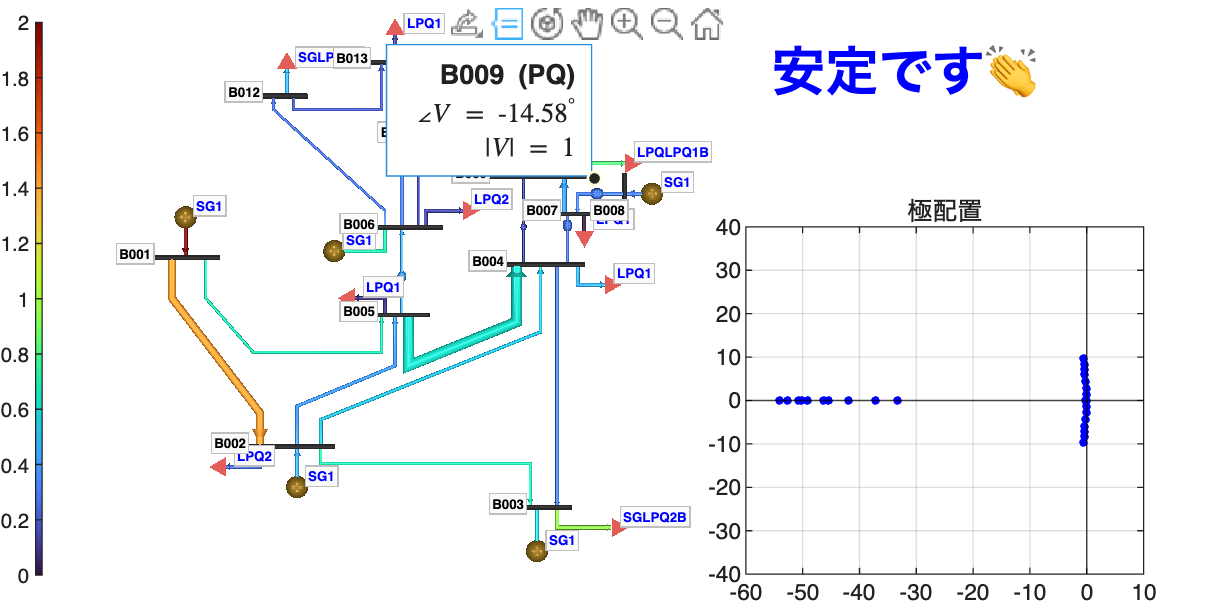

 >> グラフプロットに反映中... ok!!
 >> 極配置プロットに反映中... ok!!


alpha3 =1.46 ;


a_Component_final = tools.vcellfun(@(b) b.a_Component, net_origin.a_Bus);
mulitiple_alpha(a_Component_final, rv_defPQ_final, alpha3)
net_final.initialize;


[Graph3, txt3, sct3] = func.new_plot(net_alpha);
func.update_plot(net_final, Graph3, txt3, sct3);

% func.update_plot(net, Graph3, txt3, sct3);

## **最適選択の結果、適当にGFM・GFLの選択を行った時よりも安定度が向上していればGOODです !!**

function beta = calc_beta(Q, V, Xq)
    beta = Q + V^2/Xq;
end

function phi = calc_phi(P, Q, V, Xq)
    beta = calc_beta(Q, V, Xq);
    phi  = atan2(P, beta);
end

function gamma = calc_gamma(P, Q, V, Xq, Xd)
    phi = calc_phi(P, Q, V, Xq);
    gamma = Q + V^2*cos(phi)^2/Xq + V^2*sin(phi)^2/Xd;
end

function GFMterm = calc_GFMterm(P, Q, V, Xq, Xd)
    gamma = calc_gamma(P, Q, V, Xq, Xd);
    beta  = calc_beta(Q, V, Xq);
    phi   = calc_phi(P, Q, V, Xq);

    GFMterm = (gamma*beta + beta^2 - P^2)/(gamma * (V*sin(phi))^2) + 2/Xq;
end

function mulitiple_alpha(a_Comp, rv_defPQ, alpha)
    for i_Comp = 1:numel(a_Comp)
        para_pf = a_Comp{i_Comp}.para_powerflow;
        para_pf.P = rv_defPQ(i_Comp,1) * alpha;
        para_pf.Q = rv_defPQ(i_Comp,2) * alpha;
    end
end


function replace_component(listInverter, baseComponentName, tab_VSG, baseBus)
    
    %     pastInverter            前のステップでGFLかGFMを指定したリスト
    %     listInverter            現在のステップでGFLかGFMを指定したリスト
    %     baseComponentName       netを定義した際のコンポーネントのリスト
    %     tab_VSG                 VSGのパラメータを格納したテーブル
    %     baseBus                 3,9,12,14番目の母線オブジェクトが格納されたせる配列
    
    whichComponent = ["gen-classical";"load-power"];
    for inv = 1:numel(listInverter)
        
        baseCompName = baseComponentName(inv);
        newComponent = whichComponent( listInverter(inv) );   
    
        baseBus{inv}.replace_component(baseCompName, newComponent, tab_VSG(inv,:) );    
           
    end
end